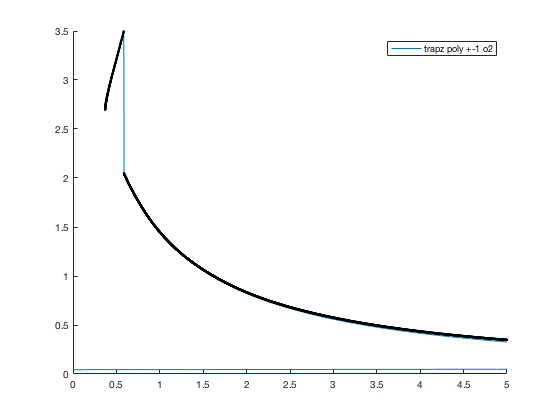


% Import theoretical data 
n_z = n_vec_TTilde;
z_i = z_TTilde_vec;

% [ TTilde_vec, CV_vec, P_sim, k_sim, mu_EF_vec ]  = SimulatedUnitarity( );

% figure;
% plot(z_i)

plotset = {0, 0.05};
bins = 0;

figure; hold on; 
legend_text = {};
i = 0;

i = i + 1;
methods = {'sum','diff',1,2};
outp = EoS_nz_KvsP_s( z_i, n_z/2, 'methods',methods,'plot',plotset,'bins',bins);
plot(outp.P_U,outp.k_U,'-');
legend_text{i} = 'sum diff';

i = i +1;
methods = {'trapz','diff',1,2};
outp = EoS_nz_KvsP_s( z_i, n_z/2, 'methods',methods,'plot',plotset,'bins',bins);
plot(outp.P_U,outp.k_U,'-');
legend_text{i} = 'trapz diff';

% i = i +1;
% methods = {'simps','diff',1,2};
% outp = EoS_nz_KvsP_s( z_i, n_z/2, 'methods',methods,'plot',plotset,'bins',bins);
% plot(outp.P_U,outp.k_U,'-');
% legend_text{i} = 'simps diff';

i = i + 1;
methods = {'trapz','poly',1,2};
outp = EoS_nz_KvsP_s( z_i, n_z/2, 'methods',methods,'plot',plotset,'bins',bins);
plot(outp.P_U,outp.k_U,'-');
legend_text{i} = 'trapz poly +-1 o2';

plot(P_sim,k_sim,'k.')

hold off;
xlim([0 5]);
legend(legend_text);